**VSI power circuit**

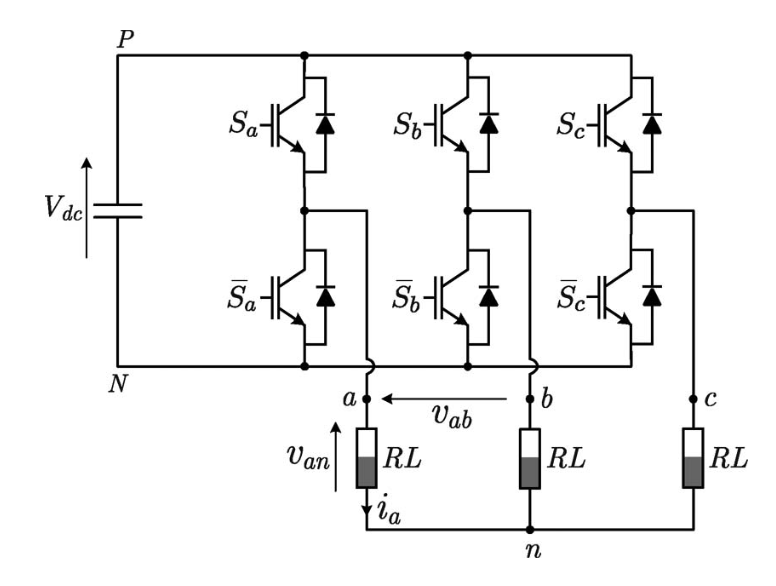

Figure from  [1]: S. Kouro, P. Cortés, R. Vargas, U. Ammann, and J. Rodríguez, “Model predictive control – a simple and powerful method to control power converters,” IEEE Transactions on Industrial Electronics, vol. 56, no. 6, pp. 1826–1838, June 2009. 

The following model followed [2]: Long-Horizon Finite-Control-Set Model Predictive Control with Non-Recursive Sphere Decoding on an FPGA,  Tinus Dorfling, Toit Mouton, Tobias Geyer, Petros Karamanakos.

**FCS**

clc, clear all, close all

Ts = 1/1000; % secCALIBRAonds
Vd = 60; % voltage
Vdc = Vd;
R = 22.5;  %127 % ohms
L = 0.10 ; % henry
x_ref = [0.5 0.5]' ;

%**************************************************************************
%                       INIT SYSTEM PARAMETERS
%**************************************************************************
% transformada clark
K = 2/3 * [1 -1/2 -1/2; 0 sqrt(3)/2 -sqrt(3)/2] ;

I_2 = eye(2);

% state matrix
F = - R/L * I_2;
G = (Vd/(2*L)) * K;
A = expm(F*Ts); % matrix exponential
B = -F^(-1) * (I_2 - A) * G;

lambda = 0.01; % switch
lambda_i = 10 ; % current


uk=[0 0 0]';

switch_state = [
    0 0 0;
    0 0 1;
    0 1 0;
    0 1 1;
    1 0 0;
    1 1 0;
    1 0 1;
    1 1 1;
];

n = (size(switch_state));
n = n(1);
np=1;


%**************************************************************************
%**************************************************************************
%**************************************************************************
%**************************************************************************
%
% POSSIBILITIES
%
%**************************************************************************
% Condicao 0 inicial
x0 = [0 ; 0];
i_alfa = x0(1); i_beta = x0(2);
u0 = [0 ; 0 ; 0];
i_alfabeta = x0;
%**************************************************************************

k_test = 30;
x = cell(k_test,1);
x{1} = x0;
u = cell(k_test,1);
x{2} = x0;

u{1} = u0;
index_min_all = zeros(k_test-1,1);
g_i_all = zeros(n,1)

g_i_all =      0
     0
     0
     0
     0
     0
     0
     0


for k = 2 : k_test
        g=zeros(n,1);

        for possibilidade=1:n
            disp ("A * x{k} ")
            disp(A * x{k} )
            disp ("B * u{k} ")
            disp(B * switch_state(possibilidade,1:end)'  )
            x_p = A * x{k} + B * switch_state(possibilidade,1:end)' ;

            g_u = norm([u{k-1} - switch_state(possibilidade,1:end)']) ;

            g_i = norm(x_ref - x_p) ;

            g(possibilidade) =  lambda * g_u + lambda_i * g_i ;
        end

        index_min_all(k) = find(g==min(g)) ;
        gi_all(k) = g(find(g==min(g))) ;
        u{k} = switch_state( find(g==min(g)) , 1:end )' ;
        x{k+1} = A * x{k} + B * u{k};
        disp(x{k})

end

A * x{k} 


     0
     0



B * u{k} 


     0
     0



A * x{k} 


     0
     0



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


     0
     0



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


     0
     0



B * u{k} 


   -0.1791
         0



A * x{k} 


     0
     0



B * u{k} 


    0.1791
         0



A * x{k} 


     0
     0



B * u{k} 


    0.0895
    0.1551



A * x{k} 


     0
     0



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


     0
     0



B * u{k} 


     0
     0



     0
     0



A * x{k} 


    0.0715
    0.1239



B * u{k} 


     0
     0



A * x{k} 


    0.0715
    0.1239



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.0715
    0.1239



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.0715
    0.1239



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.0715
    0.1239



B * u{k} 


    0.1791
         0



A * x{k} 


    0.0715
    0.1239



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.0715
    0.1239



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.0715
    0.1239



B * u{k} 


     0
     0



    0.0895
    0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


     0
     0



A * x{k} 


    0.1286
    0.2227



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.1286
    0.2227



B * u{k} 


    0.1791
         0



A * x{k} 


    0.1286
    0.2227



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


     0
     0



    0.1611
    0.2790



A * x{k} 


    0.1742
    0.3017



B * u{k} 


     0
     0



A * x{k} 


    0.1742
    0.3017



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.1742
    0.3017



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.1742
    0.3017



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.1742
    0.3017



B * u{k} 


    0.1791
         0



A * x{k} 


    0.1742
    0.3017



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.1742
    0.3017



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.1742
    0.3017



B * u{k} 


     0
     0



    0.2182
    0.3779



A * x{k} 


    0.2106
    0.3648



B * u{k} 


     0
     0



A * x{k} 


    0.2106
    0.3648



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.2106
    0.3648



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.2106
    0.3648



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.2106
    0.3648



B * u{k} 


    0.1791
         0



A * x{k} 


    0.2106
    0.3648



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.2106
    0.3648



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.2106
    0.3648



B * u{k} 


     0
     0



    0.2637
    0.4568



A * x{k} 


    0.3112
    0.2913



B * u{k} 


     0
     0



A * x{k} 


    0.3112
    0.2913



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3112
    0.2913



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3112
    0.2913



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3112
    0.2913



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3112
    0.2913



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3112
    0.2913



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3112
    0.2913



B * u{k} 


     0
     0



    0.3897
    0.3648



A * x{k} 


    0.3200
    0.3564



B * u{k} 


     0
     0



A * x{k} 


    0.3200
    0.3564



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3200
    0.3564



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3200
    0.3564



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3200
    0.3564



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3200
    0.3564



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3200
    0.3564



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3200
    0.3564



B * u{k} 


     0
     0



    0.4007
    0.4464



A * x{k} 


    0.3270
    0.4085



B * u{k} 


     0
     0



A * x{k} 


    0.3270
    0.4085



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3270
    0.4085



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3270
    0.4085



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3270
    0.4085



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3270
    0.4085



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3270
    0.4085



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3270
    0.4085



B * u{k} 


     0
     0



    0.4095
    0.5115



A * x{k} 


    0.4041
    0.3262



B * u{k} 


     0
     0



A * x{k} 


    0.4041
    0.3262



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4041
    0.3262



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4041
    0.3262



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4041
    0.3262



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4041
    0.3262



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4041
    0.3262



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4041
    0.3262



B * u{k} 


     0
     0



    0.5061
    0.4085



A * x{k} 


    0.3942
    0.3843



B * u{k} 


     0
     0



A * x{k} 


    0.3942
    0.3843



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3942
    0.3843



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3942
    0.3843



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3942
    0.3843



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3942
    0.3843



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3942
    0.3843



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3942
    0.3843



B * u{k} 


     0
     0



    0.4937
    0.4813



A * x{k} 


    0.3863
    0.4307



B * u{k} 


     0
     0



A * x{k} 


    0.3863
    0.4307



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3863
    0.4307



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3863
    0.4307



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3863
    0.4307



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3863
    0.4307



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3863
    0.4307



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3863
    0.4307



B * u{k} 


     0
     0



    0.4838
    0.5394



A * x{k} 


    0.3800
    0.4678



B * u{k} 


     0
     0



A * x{k} 


    0.3800
    0.4678



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3800
    0.4678



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3800
    0.4678



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3800
    0.4678



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3800
    0.4678



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3800
    0.4678



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3800
    0.4678



B * u{k} 


     0
     0



    0.4758
    0.5858



A * x{k} 


    0.4464
    0.3735



B * u{k} 


     0
     0



A * x{k} 


    0.4464
    0.3735



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4464
    0.3735



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4464
    0.3735



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4464
    0.3735



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4464
    0.3735



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4464
    0.3735



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4464
    0.3735



B * u{k} 


     0
     0



    0.5591
    0.4678



A * x{k} 


    0.4280
    0.4221



B * u{k} 


     0
     0



A * x{k} 


    0.4280
    0.4221



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4280
    0.4221



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4280
    0.4221



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4280
    0.4221



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4280
    0.4221



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4280
    0.4221



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4280
    0.4221



B * u{k} 


     0
     0



    0.5360
    0.5286



A * x{k} 


    0.4133
    0.4609



B * u{k} 


     0
     0



A * x{k} 


    0.4133
    0.4609



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4133
    0.4609



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4133
    0.4609



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4133
    0.4609



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4133
    0.4609



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4133
    0.4609



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4133
    0.4609



B * u{k} 


     0
     0



    0.5175
    0.5772



A * x{k} 


    0.3300
    0.3681



B * u{k} 


     0
     0



A * x{k} 


    0.3300
    0.3681



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3300
    0.3681



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3300
    0.3681



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3300
    0.3681



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3300
    0.3681



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3300
    0.3681



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3300
    0.3681



B * u{k} 


     0
     0



    0.4133
    0.4609



A * x{k} 


    0.3350
    0.4178



B * u{k} 


     0
     0



A * x{k} 


    0.3350
    0.4178



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3350
    0.4178



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3350
    0.4178



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3350
    0.4178



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3350
    0.4178



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3350
    0.4178



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3350
    0.4178



B * u{k} 


     0
     0



    0.4195
    0.5232



A * x{k} 


    0.4105
    0.3336



B * u{k} 


     0
     0



A * x{k} 


    0.4105
    0.3336



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4105
    0.3336



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4105
    0.3336



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4105
    0.3336



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4105
    0.3336



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4105
    0.3336



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4105
    0.3336



B * u{k} 


     0
     0



    0.5141
    0.4178



A * x{k} 


    0.3993
    0.3902



B * u{k} 


     0
     0



A * x{k} 


    0.3993
    0.3902



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3993
    0.3902



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3993
    0.3902



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3993
    0.3902



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3993
    0.3902



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3993
    0.3902



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3993
    0.3902



B * u{k} 


     0
     0



    0.5001
    0.4887



A * x{k} 


    0.3904
    0.4355



B * u{k} 


     0
     0



A * x{k} 


    0.3904
    0.4355



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3904
    0.4355



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3904
    0.4355



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3904
    0.4355



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3904
    0.4355



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3904
    0.4355



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3904
    0.4355



B * u{k} 


     0
     0



    0.4889
    0.5453



A * x{k} 


    0.3832
    0.4716



B * u{k} 


     0
     0



A * x{k} 


    0.3832
    0.4716



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3832
    0.4716



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3832
    0.4716



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3832
    0.4716



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3832
    0.4716



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3832
    0.4716



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3832
    0.4716



B * u{k} 


     0
     0



    0.4799
    0.5906



A * x{k} 


    0.4490
    0.3766



B * u{k} 


     0
     0



A * x{k} 


    0.4490
    0.3766



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4490
    0.3766



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4490
    0.3766



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4490
    0.3766



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4490
    0.3766



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4490
    0.3766



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4490
    0.3766



B * u{k} 


     0
     0



    0.5623
    0.4716



A * x{k} 


    0.4301
    0.4245



B * u{k} 


     0
     0



A * x{k} 


    0.4301
    0.4245



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4301
    0.4245



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4301
    0.4245



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4301
    0.4245



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4301
    0.4245



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4301
    0.4245



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4301
    0.4245



B * u{k} 


     0
     0



    0.5386
    0.5317



A * x{k} 


    0.4149
    0.4629



B * u{k} 


     0
     0



A * x{k} 


    0.4149
    0.4629



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4149
    0.4629



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4149
    0.4629



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4149
    0.4629



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4149
    0.4629



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4149
    0.4629



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4149
    0.4629



B * u{k} 


     0
     0



    0.5196
    0.5796



A * x{k} 


    0.3313
    0.3696



B * u{k} 


     0
     0



A * x{k} 


    0.3313
    0.3696



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3313
    0.3696



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3313
    0.3696



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3313
    0.3696



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3313
    0.3696



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3313
    0.3696



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3313
    0.3696



B * u{k} 


     0
     0



    0.4149
    0.4629



A * x{k} 


    0.3361
    0.4190



B * u{k} 


     0
     0



A * x{k} 


    0.3361
    0.4190



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3361
    0.4190



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3361
    0.4190



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3361
    0.4190



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3361
    0.4190



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3361
    0.4190



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3361
    0.4190



B * u{k} 


     0
     0



    0.4209
    0.5247



A * x{k} 


    0.4114
    0.3346



B * u{k} 


     0
     0



A * x{k} 


    0.4114
    0.3346



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4114
    0.3346



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4114
    0.3346



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4114
    0.3346



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4114
    0.3346



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4114
    0.3346



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4114
    0.3346



B * u{k} 


     0
     0



    0.5152
    0.4190



A * x{k} 


    0.4000
    0.3910



B * u{k} 


     0
     0



A * x{k} 


    0.4000
    0.3910



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4000
    0.3910



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4000
    0.3910



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4000
    0.3910



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4000
    0.3910



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4000
    0.3910



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4000
    0.3910



B * u{k} 


     0
     0



    0.5009
    0.4897



A * x{k} 


    0.3909
    0.4361



B * u{k} 


     0
     0



A * x{k} 


    0.3909
    0.4361



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3909
    0.4361



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3909
    0.4361



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3909
    0.4361



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3909
    0.4361



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3909
    0.4361



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3909
    0.4361



B * u{k} 


     0
     0



    0.4895
    0.5461




i_alfa = zeros(k_test, 1);
i_beta = zeros(k_test, 1);
i_a_all = zeros(k_test, 1);
i_b_all = zeros(k_test, 1);
i_c_all = zeros(k_test, 1);
i_abc=  zeros(k_test, 3);
ua = zeros(k_test, 1);
ub = zeros(k_test, 1);
uc = zeros(k_test, 1);
vf_all= zeros(k_test, 1);
i_all = cell2mat(x);
u_all = cell2mat(u);
size_i_all = size(i_all);
size_i_all = size_i_all(1);

cont = 1;
for i = 3:2:size_i_all
    i_alfa(cont) = i_all(i);
    cont = cont + 1;
end
cont = 1;
for i = 4:2:size_i_all
    i_beta(cont) = i_all(i);
    cont = cont + 1;
end
for i = 1:k_test
    ik = K * [1, 0 ; 0, 1; -1, -1] * [i_alfa(i); i_beta(i)]
    ia = ik(1)
    ib = ik(2)
    ic= ia-ib;

    i_a_all(i) = ia ;
    i_b_all(i) = ib ;
    i_c_all(i) = ic;
    i_abc(i,1:3) = [ia ; ib ; ic ];
end

ik =      0
     0


ia = 0

ib = 0

ik =     0.0895
    0.2308


ia = 0.0895

ib = 0.2308

ik =     0.1611
    0.4151


ia = 0.1611

ib = 0.4151

ik =     0.2182
    0.5623


ia = 0.2182

ib = 0.5623

ik =     0.2637
    0.6798


ia = 0.2637

ib = 0.6798

ik =     0.3897
    0.6462


ia = 0.3897

ib = 0.6462

ik =     0.4007
    0.7468


ia = 0.4007

ib = 0.7468

ik =     0.4095
    0.8271


ia = 0.4095

ib = 0.8271

ik =     0.5061
    0.7639


ia = 0.5061

ib = 0.7639

ik =     0.4937
    0.8408


ia = 0.4937

ib = 0.8408

ik =     0.4838
    0.9022


ia = 0.4838

ib = 0.9022

ik =     0.4758
    0.9512


ia = 0.4758

ib = 0.9512

ik =     0.5591
    0.8629


ia = 0.5591

ib = 0.8629

ik =     0.5360
    0.9199


ia = 0.5360

ib = 0.9199

ik =     0.5175
    0.9653


ia = 0.5175

ib = 0.9653

ik =     0.4133
    0.7708


ia = 0.4133

ib = 0.7708

ik =     0.4195
    0.8463


ia = 0.4195

ib = 0.8463

ik =     0.5141
    0.7792


ia = 0.5141

ib = 0.7792

ik =     0.5001
    0.8530


ia = 0.5001

ib = 0.8530

ik =     0.4889
    0.9119


ia = 0.4889

ib = 0.9119

ik =     0.4799
    0.9590


ia = 0.4799

ib = 0.9590

ik =     0.5623
    0.8692


ia = 0.5623

ib = 0.8692

ik =     0.5386
    0.9248


ia = 0.5386

ib = 0.9248

ik =     0.5196
    0.9693


ia = 0.5196

ib = 0.9693

ik =     0.4149
    0.7740


ia = 0.4149

ib = 0.7740

ik =     0.4209
    0.8489


ia = 0.4209

ib = 0.8489

ik =     0.5152
    0.7812


ia = 0.5152

ib = 0.7812

ik =     0.5009
    0.8546


ia = 0.5009

ib = 0.8546

ik =     0.4895
    0.9132


ia = 0.4895

ib = 0.9132

ik =     0.4805
    0.9600


ia = 0.4805

ib = 0.9600

cont = 1;
for i = 1:3:length(u_all)
    ua(cont) = u_all(i);
    cont = cont + 1;
end
cont = 1;
for i = 2:3:length(u_all)
    ub(cont) = u_all(i);
    cont = cont + 1;
end
cont = 1;
for i = 3:3:length(u_all)
    uc(i) = u_all(i);
    cont = cont + 1;
end
for i = 1:k_test
    vf_all(i) = 2/3 * (Vdc/2 * ua(i) * exp(j*0) + Vdc/2 * ub(i) * exp(j*2/3) + Vdc/2 * uc(i) * exp(j*4*pi/3) );
end




% plot control
figure
x=5;
colors = {'r', 'g', 'b', 'm', 'c', 'y', 'k', 'r', 'g'};
hold on;
xlabel('k'), ylabel(' I [A] ');
legend('x_1(t)', 'x_2(t)')

sgtitle('Plot \lambda = 0.01 ; \lambda_i = 1 ; x_{ref} = [.5 .5]; T_s = 5e-05');

subplot(x,1,1);
plot(i_a_all, colors{5}); hold on;
plot(i_b_all, colors{4}); hold on;
legend('ia_{leg A}', 'ib_{leg B} ')
ylabel('A');
grid on;

subplot(x,1,2);
plot(i_alfa, colors{5});hold on;
plot(i_beta, colors{4});hold on;

legend('i alfa ', 'i beta ')
xlabel('k'), ylabel(' I [A] ')
grid on;

subplot(x,1,3);
plot(ua, colors{1}); hold on;
xlabel('k'), ylabel(' switch A ')

subplot(x,1,4);
plot(ub, colors{2}); hold on;
xlabel('k'), ylabel(' switch B ')

subplot(x,1,5);
plot(uc, colors{3}); hold on;
xlabel('k'), ylabel(' switch C ')

axis([-0.5 length(ua)+1 -0.1 1.1]);
grid on;



**2L VSI GPC**

%% State-Space Model for GPC with PWM 
% This script implements GPC control with PWM modulation for a 3-phase VSI
clear; clc; close all;


**Frame reference**

%% Parâmetros
f = 60;              % Frequência fundamental (Hz)
T = 0.04;            % Tempo total (40 ms)
fs = 100000;         % Frequência de amostragem
t = 0:1/fs:T;
omega = 2*pi*f;
Am_reference = 5;    % Amplitude do sinal de referência

%% Geração das três fases (abc)
Va = Am_reference * sin(omega*t);
Vb = Am_reference * sin(omega*t - 2*pi/3);
Vc = Am_reference * sin(omega*t - 4*pi/3);


%% Clark Transformation Matrix
K = 2/3 * [1 -1/2 -1/2; 0 sqrt(3)/2 -sqrt(3)/2];
K_inv = [1 0; -1/2 sqrt(3)/2; -1/2 -sqrt(3)/2]; % Inverse Clark

I_2 = eye(2);

%% Transformação de Clarke (α-β)
K_clarke = (2/3) * [1 -0.5 -0.5; 0 sqrt(3)/2 -sqrt(3)/2];
alpha_beta = K_clarke * [Va; Vb; Vc];
alpha = alpha_beta(1,:);
beta  = alpha_beta(2,:);

%% Transformação de Park (d-q) conforme fórmula da imagem
theta = omega*t;
% Aplicar Park elemento a elemento
d = sqrt(2/3) * (Va .* cos(theta) + Vb .* cos(theta - 2*pi/3) + Vc .* cos(theta - 4*pi/3));
q = sqrt(2/3) * (-Va .* sin(theta) - Vb .* sin(theta - 2*pi/3) - Vc .* sin(theta - 4*pi/3));

%% Plotagem
figure;
subplot(3,1,1);
plot(t*1000, Va, 'r', t*1000, Vb, 'g', t*1000, Vc, 'b');
title('Sinais trifásicos (abc)');
xlabel('Tempo (ms)'); ylabel('Amplitude');
legend('Va','Vb','Vc'); grid on;

subplot(3,1,2);
plot(t*1000, alpha, 'r', t*1000, beta, 'g');
title('Clarke (α-β)');
xlabel('Tempo (ms)'); ylabel('Amplitude');
legend('α','β'); grid on;

subplot(3,1,3);
plot(t*1000, d, 'c', t*1000, q, 'm');
title('Park (d-q)');
xlabel('Tempo (ms)'); ylabel('Amplitude');
legend('d','q'); grid on;

**System Parameters**

*In a pulse width modulator, the reference voltage is compared to a triangular carrier signal and the output of the comparator is used to drive the inverter switches. The application of a pulse width modulator in a single-phase inverter is shown. A sinusoidal reference voltage is compared to the triangular carrier signal generating a pulsed voltage waveform at the output of the inverter. The fundamental component of this voltage is proportional to the reference voltage. In a three-phase inverter, the reference voltage of each phase is compared to the triangular waveform, generating the switching states for each corresponding inverter leg. Output voltages for phases a and b, vaN and vbN , and line-to-line voltage vab are also shown in the following code.*

*A modulacao por pulsos é uma alternativa para implementar uma atuacao proporcional usando um atuador tipo liga-desliga. Caso a frequencia usada para ligar e desligar o atuador seja muito maior que o inverso do período de tempo médio das dinâmicas do sistema, entao, potemos considerar que o sistema recebe uma atuacao dada pelo valor médio do sinal de tensao enviado. O conceito associado ao controle Proporcional-Integral é o seguinte: a ação de controle PI é composta por duas parcelas, uma delas proporcional ao erro de seguinmento e a outra à integral do erro de seguimento. O principal objetivo é garantir que a variável de processo se mantenha, em regime permanente, emum valor de referência desejado.*

Para muitas análises, podemos simplificar o motor representando cada fase por um circuito resistivo-indutivo (R–L) alimentado por uma fonte senoidal.


$$v\left(t\right)=\textrm{Ri}\left(t\right)+\frac{\textrm{Ldi}\left(t\right)}{\textrm{dt}}$$


Model RLC from [3] Diego Rojas, Marco Rivera, Sergio Toledo, and Patrick Wheeler. Predictive control techniques applied to a 2L-VSI.

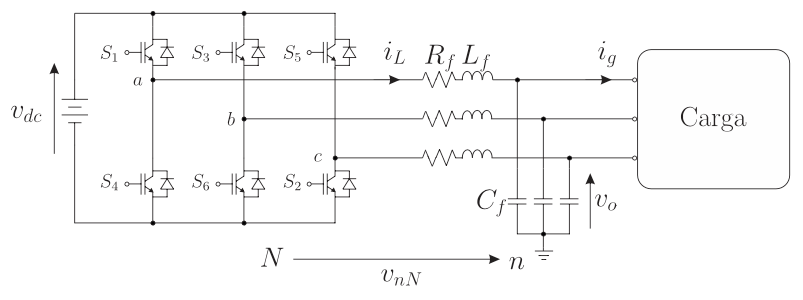

**GPC SISO**

clear; 
clc; 
%close all;

% Time parameters
f_sw = 10e3;            % Switching frequency [Hz]
f_fund = 60;            % Fundamental frequency [Hz]
Ts = 1/f_sw;            % Sampling time [s]
Tsim = 0.1;             % Simulation time [s]

%% Clark Transformation Matrices
K_clark = 2/3 * [1 -1/2 -1/2; 0 sqrt(3)/2 -sqrt(3)/2];
K=K_clark;
K_clark_inv = [1 0; -1/2 sqrt(3)/2; -1/2 -sqrt(3)/2];
I_2 = eye(2);


Vdc = 60;               % DC link voltage [V]
Vd=Vdc;
R = 3.5;                % Resistance [Ω]
L = 0.1;                % Inductance [H]

%% Parâmetros do sistema
F = -R/L * I_2;
G = (Vd/(2*L)) * K;
Ts = 1e-4; 


A1 = expm(F*Ts); % matriz A discreta
B1 = -F^(-1) * (I_2 - A1) * G; % matriz B discreta
C1 = [1 0]; % exemplo de saída
C=C1;
D1 = 0;
D=D1;

sysc = ss(F, G, C1, D1);
sysd = c2d(sysc, Ts, 'zoh');

Ad = sysd.A;
Bd = sysd.B;


Tz = tf(sysd);
A = cell2mat(Tz.den);   % coeficientes A(z^-1)
B = cell2mat(Tz.num);   % coeficientes B(z^-1)

% Incluir atraso de 1 amostra
delay_samples = 1; % número de atrasos
Bq = [zeros(1, delay_samples) B]; % adiciona zeros no início para atraso

fprintf('A(z^-1): '); disp(A);

A(z^-1):     1.0000   -0.9965    1.0000   -0.9965    1.0000   -0.9965



fprintf('B(z^-1) com atraso: '); disp(Bq);

B(z^-1) com atraso:          0         0    0.0200         0   -0.0100         0   -0.0100




Bq = [0 Bq]; % numerador do modelo da perturbação do processo

fprintf('Discrete Model:\n');

Discrete Model:



% Exibir matriz A
fprintf('A = [\n');

A = [


for i = 1:size(A,1)
    fprintf('%.6f ', A(i,:));
end

1.000000 -0.996506 1.000000 -0.996506 1.000000 -0.996506 

fprintf(']\n');

]



% Exibir matriz B
fprintf('B = [\n');

B = [


for i = 1:size(B,1)
    fprintf('%.6f ', B(i,:));
end

0.000000 0.019965 0.000000 -0.009983 0.000000 -0.009983 

fprintf(']\n\n');

]




%%  GPC Parameters
d = 0;                  % Input delay
N1 = 1;                 % Minimum prediction horizon
N2 = 10;                % Maximum prediction horizon  
Nu = 3;                 % Control horizon
N = N2 - N1 + 1;        % Prediction horizon length

delta = 1;              % Output error weight
lambda = 0.1;           % Control effort weight

fprintf('   GPC PARAMETERS   \n');

   GPC PARAMETERS   


fprintf('N1=%d, N2=%d, Nu=%d, N=%d\n', N1, N2, Nu, N);

N1=1, N2=10, Nu=3, N=10


fprintf('delta=%.1f, lambda=%.1f\n\n', delta, lambda);

delta=1.0, lambda=0.1




%% Build GPC Matrices
na = length(A) - 1;
nb = length(B) - 1;

% Incorporate delay
Btil = conv(B, [zeros(1,d) 1]);

% Calculate Diophantine polynomials
[E, F] = diofantina(conv(A, [1 -1]), N1, N2);

% Build dynamic matrix G
G = zeros(N, Nu);
H = zeros(N, nb + d);

for i = N1:N2
    j = i - N1 + 1;
    EjB = conv(E(j, 1:i), Btil);
    
    % Fill G matrix (future control actions)
    if i <= Nu
        G(j, 1:i) = EjB(i:-1:1);
    else
        G(j, :) = EjB(i:-1:i-Nu+1);
    end
    
    % Fill H matrix (past control actions)
    if length(EjB) > i
        H(j, 1:min(nb+d, length(EjB)-i)) = EjB(i+1:end);
    end
end

% GPC gain calculation
Qe = delta * eye(N);
Qu = lambda * eye(Nu);
K_gpc = (G' * Qe * G + Qu) \ (G' * Qe);

K_gpc1 = K_gpc(1, :);  % First row for current control
Kmpc1 = K_gpc(1,:);


fprintf('Matrix Dimensions:\n');

Matrix Dimensions:


fprintf('G: %dx%d, K_gpc: %dx%d\n\n', size(G,1), size(G,2), size(K_gpc,1), size(K_gpc,2));

G: 10x3, K_gpc: 3x10



G,F,H

G =          0         0         0
    0.0200         0         0
    0.0399    0.0200         0
    0.0297    0.0399    0.0200
    0.0197    0.0297    0.0399
    0.0096    0.0197    0.0297
   -0.0004    0.0096    0.0197
    0.0196   -0.0004    0.0096
    0.0394    0.0196   -0.0004
    0.0293    0.0394    0.0196


F =     1.9965   -1.9965    1.9965   -1.9965    1.9965   -0.9965
    1.9895   -1.9895    1.9895   -1.9895    2.9895   -1.9895
    1.9826   -1.9826    1.9826   -0.9826    1.9826   -1.9826
    1.9757   -1.9757    2.9757   -1.9757    1.9757   -1.9757
    1.9687   -0.9687    1.9687   -1.9687    1.9687   -1.9687
    2.9619   -1.9619    1.9619   -1.9619    1.9619   -1.9619
    3.9515   -3.9515    3.9515   -3.9515    3.9515   -2.9515
    3.9377   -3.9377    3.9377   -3.9377    4.9377   -3.9377
    3.9240   -3.9240    3.9240   -2.9240    3.9240   -3.9240
    3.9102   -3.9102    4.9102   -3.9102    3.9102   -3.9102


H =     0.0200         0   -0.0100         0   -0.0100
    0.0399   -0.0100   -0.0199   -0.0100   -0.0199
    0.0297   -0.0199   -0.0298   -0.0199   -0.0199
    0.0197   -0.0298   -0.0397   -0.0199   -0.0198
    0.0096   -0.0397   -0.0396   -0.0198   -0.0197
   -0.0004   -0.0396   -0.0394   -0.0197   -0.0197
    0.0196   -0.0394   -0.0493   -0.0197   -0.0296
    0.0394   -0.0493   -0.0591   -0.0296   -0.0394
    0.0293   -0.0591   -0.0689   -0.0394   -0.0393
    0.0192   -0.0689   -0.0786   -0.0393   -0.0392



A_tilde = conv([1 -1], A);  % ΔA = (1-z^-1)A(z^-1)
fprintf('A:\n');

A:


A

A =     1.0000   -0.9965    1.0000   -0.9965    1.0000   -0.9965


fprintf('A til:\n');

A til:


A_tilde

A_tilde =     1.0000   -1.9965    1.9965   -1.9965    1.9965   -1.9965    0.9965




Nsim = 100;
t = 1:Nsim;

% Entrada (degraus)
u = zeros(Nsim, 1);
u(20:40) = 1;
u(60:80) = -0.5;

% Ruído colorido (filtrado por C)
e = 0.1 * randn(Nsim, 1);  % Ruído branco
xi = zeros(Nsim, 1);       % Ruído colorido

for k = 3:Nsim
    if k > 2
        xi(k) = e(k) + C(2)*xi(k-1) ; %+ C(3)*xi(k-2);
    end
end

% Saída do sistema
y = zeros(Nsim, 1);
y_clean = zeros(Nsim, 1);  % Sem ruído

for k = 3:Nsim
    % Sem ruído
    y_clean(k) = -A(2)*y_clean(k-1) + ... % - A(3)*y_clean(k-2) + ...
                 B(1)*u(max(1,k-d)) ; %+ B(2)*u(max(1,k-d-1));
    
    % Com ruído
    y(k) = -A(2)*y(k-1) + ... - A(3)*y(k-2) + ...
            B(1)*u(max(1,k-d))  + xi(k); % + B(2)*u(max(1,k-d-1))
end

%% Predição um passo à frente
y_pred = zeros(Nsim, 1);

for k = 4:Nsim
    % Forma incremental do modelo:
    % A_tilde * y(k) = B * Δu(k-1) + C * e(k)
    
    % Predição: ŷ(k|k-1) = [B/A_tilde] Δu(k-1) + [1 - C/A_tilde] y(k-1)
    
    % Parte forçada
    delta_u = u(k-d) - u(k-d-1);
    forced_part = filter(B, A_tilde, delta_u);
    
    % Parte livre (aproximação)
    free_part = y(k-1) - filter(C, A_tilde, y(k-1));
    
    y_pred(k) = forced_part + free_part;
end
u

u =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


**GPC SISO perturbação**

% % hardware lab measurements
% Ts = 1e-2;  % Sampling time
% Vd = 100; VDC = Vd;Vdc = Vd;  % voltage
% R = 3.5;  %3.5 % ohms
% L = 0.0025 ; % henry
% 
% % Example parameters for a typical LC filter
% Rf = 0.1;        % Resistance [Ω]
% Lf = 1e-3;       % Inductance [mH]
% Cf = 10e-6;      % Capacitance [μF]
% Ts_filter = 100e-6;   %  [100 μs = 10 kHz]
% 
% %% Continuous-Time State-Space Matrices
% A1 = [-Rf/Lf,  -1/Lf;
%        1/Cf,    0   ]
% Ad = expm(A1 * Ts);
% B = [1/Lf,     0;
%          0,    -1/Cf];

% B1 = [Vdc/Lf;  0];
% C1 = [1 0];

% D1 = 0;
% [Bc, Ac] = ss2tf(A1, B1, C1, D1);
% Tz = c2d(tf(Bc, Ac), Ts) % Discretized
% A = cell2mat(Tz.den); %   A(z-¹)
% B = cell2mat(Tz.num); %   B(z-¹)
% C = [1 0];
% D = 0;
% Bq = [0.001]; % numerador do modelo da perturbação do processo

% % state-space system
% sysc = ss(A, B, C, D); 
% sysd = ss(A, B, C, D, Ts);
% A = [sysd.A]

%[Ad,Bd] = c2dm(sysc.A,sysc.B,sysc.C,[0 0],Ts,'zoh')
i_L_k = 5;       % 5 A
v_alpha_k = 230; % 230 V
v_o_k = 220;     % 220 V
i_g_k = 4.5;     % 4.5 A

d=0; % atraso em relação à manipulada
dq = 0; % atraso em relação à perturbação

nb = size(B,2)-1; % ordem do polinômio B
na = size(A,2)-1; % ordem do polinômio A
nbq = size(Bq,2)-1; % ordem do polinômio Bq

%% parâmetros de ajuste
N1 = 1; %horizonte de predição inicial
N2 = 30; % horizonte de predição final
N = N2-N1+1; % horizonte de predição
Nu = 3; % horizonte de controle
Nq = 0; % horizonte da ação antecipativa

delta = 1; % ponderação do erro futuro
lambda = 1; % ponderação do esforço de controle

%% montagem das matrizes
Btil = conv(B,[zeros(1,d) 1]); % incorporação do atraso no numerador B
Bqtil = conv(Bq,[zeros(1,dq) 1]); % incorporação do atraso no numerador Bq

G = zeros(N,N); % matriz dinâmica G
H = zeros(N,nb+d); % matriz dos incrementos passados de controle 
Gq = zeros(N,N-1); % matris dos incrementos da perturbação futura
Hq = zeros(N,nbq+dq); % matriz dos incrementos passados da perturbação 

[E,F] = diofantina(conv2(A,[1 -1]),N1,N2); % obtenção dos polinômios Ej, Fj

for i=N1:N2
    EjB = conv2(E(i-N1+1,1:i),Btil);
    EjBq = conv2(E(i-N1+1,1:i),Bqtil);
    
    G(i-N1+1,1:i) = EjB(i:-1:1);    
    H(i-N1+1,:) = EjB(i+1:end);

    Gq(i-N1+1,1:i) = EjBq(i:-1:1);    
    Hq(i-N1+1,:) = EjBq(i+1:end);
    
end
G = G(:,1:Nu);
Gq = Gq(:,1:Nq);


G,F,H,Gq,Hq

G =          0         0         0
    0.0200         0         0
    0.0399    0.0200         0
    0.0297    0.0399    0.0200
    0.0197    0.0297    0.0399
    0.0096    0.0197    0.0297
   -0.0004    0.0096    0.0197
    0.0196   -0.0004    0.0096
    0.0394    0.0196   -0.0004
    0.0293    0.0394    0.0196


F =     1.9965   -1.9965    1.9965   -1.9965    1.9965   -0.9965
    1.9895   -1.9895    1.9895   -1.9895    2.9895   -1.9895
    1.9826   -1.9826    1.9826   -0.9826    1.9826   -1.9826
    1.9757   -1.9757    2.9757   -1.9757    1.9757   -1.9757
    1.9687   -0.9687    1.9687   -1.9687    1.9687   -1.9687
    2.9619   -1.9619    1.9619   -1.9619    1.9619   -1.9619
    3.9515   -3.9515    3.9515   -3.9515    3.9515   -2.9515
    3.9377   -3.9377    3.9377   -3.9377    4.9377   -3.9377
    3.9240   -3.9240    3.9240   -2.9240    3.9240   -3.9240
    3.9102   -3.9102    4.9102   -3.9102    3.9102   -3.9102


H =     0.0200         0   -0.0100         0   -0.0100
    0.0399   -0.0100   -0.0199   -0.0100   -0.0199
    0.0297   -0.0199   -0.0298   -0.0199   -0.0199
    0.0197   -0.0298   -0.0397   -0.0199   -0.0198
    0.0096   -0.0397   -0.0396   -0.0198   -0.0197
   -0.0004   -0.0396   -0.0394   -0.0197   -0.0197
    0.0196   -0.0394   -0.0493   -0.0197   -0.0296
    0.0394   -0.0493   -0.0591   -0.0296   -0.0394
    0.0293   -0.0591   -0.0689   -0.0394   -0.0393
    0.0192   -0.0689   -0.0786   -0.0393   -0.0392



Gq =

  30×0 empty double matrix



Hq =          0         0    0.0200         0   -0.0100         0   -0.0100
         0    0.0200    0.0399   -0.0100   -0.0199   -0.0100   -0.0199
    0.0200    0.0399    0.0297   -0.0199   -0.0298   -0.0199   -0.0199
    0.0399    0.0297    0.0197   -0.0298   -0.0397   -0.0199   -0.0198
    0.0297    0.0197    0.0096   -0.0397   -0.0396   -0.0198   -0.0197
    0.0197    0.0096   -0.0004   -0.0396   -0.0394   -0.0197   -0.0197
    0.0096   -0.0004    0.0196   -0.0394   -0.0493   -0.0197   -0.0296
   -0.0004    0.0196    0.0394   -0.0493   -0.0591   -0.0296   -0.0394
    0.0196    0.0394    0.0293   -0.0591   -0.0689   -0.0394   -0.0393
    0.0394    0.0293    0.0192   -0.0689   -0.0786   -0.0393   -0.0392



%% obtenção do ganho irrestrito
Qu = lambda*eye(Nu); % matriz de ponderação dos incrementos de controle
Qe = delta*eye(N);  % matriz de ponderaão dos erros futuros

Kmpc = (G'*Qe*G+Qu)\G'*Qe;

Kmpc1 = Kmpc(1,:);


**GPC MIMO**

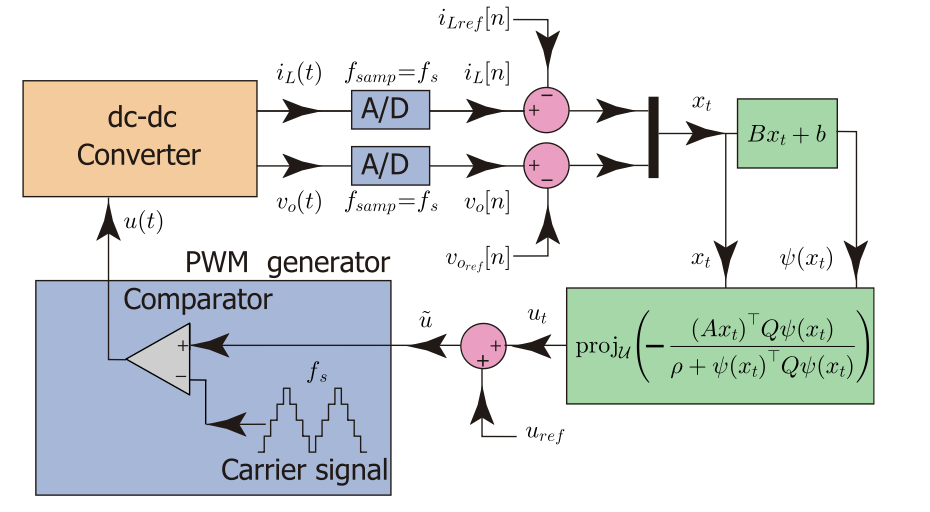

Figure from  [3]: Model Predictive Control With Stability Guarantee for Second-Order DC/DC Converters. Alejandro Garcés-Ruiz , Senior Member, IEEE, Sebastián Riffo , Catalina González-Castaño, and Carlos Restrepo.


% Definição de variáveis
m = 2; % número de ENTRADAS: [Vd, Vq]
n = 2; % número de SAÍDAS: [Id, Iq]
mq = 2; % número de PERTURBAÇÕES: [ΔVdc, Δωe]

s = tf('s');
tau = L/R;  % Constante de tempo

%--- MODELO DESACOPLADO ---
fprintf('\nMODELO DESACOPLADO:\n');


MODELO DESACOPLADO:



%% Parâmetros do sistema
F = -R/L * I_2;
G = (Vd/(2*L)) * K;
Ts = 1e-4; % exemplo de tempo de amostragem

% Discretização exata
A1 = expm(F*Ts); % matriz A discreta
B1 = -F^(-1) * (I_2 - A1) * G; % matriz B discreta
C1 = [1 0]; % exemplo de saída
D1 = 0;

sysc = ss(F, G, C1, D1);
sysd = c2d(sysc, Ts, 'zoh');

Ad = sysd.A;
Bd = sysd.B;

% Extrair função de transferência discreta
Tz = tf(sysd);
A = cell2mat(Tz.den);   % coeficientes A(z^-1)
B = cell2mat(Tz.num);   % coeficientes B(z^-1)

% Incluir atraso de 1 amostra
delay_samples = 1; % número de atrasos
Bq = [zeros(1, delay_samples) B]; % adiciona zeros no início para atraso

fprintf('A(z^-1): '); disp(A);

A(z^-1):     1.0000   -0.9965    1.0000   -0.9965    1.0000   -0.9965



fprintf('B(z^-1) com atraso: '); disp(Bq);

B(z^-1) com atraso:          0         0    0.0200         0   -0.0100         0   -0.0100





% G(1,1): Id / Vd
G_des(1,1) = (1/L) / (s + R/L);
fprintf('G(1,1) = Id/Vd = %.2f / (%.4f*s + 1)\n', (1/L)*tau, tau);

G(1,1) = Id/Vd = 0.29 / (0.0286*s + 1)



% G(1,2): Id / Vq (desacoplado = 0)
G_des(1,2) = 0;
fprintf('G(1,2) = Id/Vq = 0 (desacoplado)\n');

G(1,2) = Id/Vq = 0 (desacoplado)



% G(2,1): Iq / Vd (desacoplado = 0)
G_des(2,1) = 0;
fprintf('G(2,1) = Iq/Vd = 0 (desacoplado)\n');

G(2,1) = Iq/Vd = 0 (desacoplado)



% G(2,2): Iq / Vq
G_des(2,2) = (1/L) / (s + R/L);
fprintf('G(2,2) = Iq/Vq = %.2f / (%.4f*s + 1)\n', (1/L)*tau, tau);

G(2,2) = Iq/Vq = 0.29 / (0.0286*s + 1)



%% parâmetros  
Ts  = 1e-3;    % s
Vd  = 60;      % V (ou Vdc)
R   = 22.5;    % ohms
L   = 0.10;    % H

% matrizes elementares
I2 = eye(2);

% Clarke (abc -> alpha-beta) 2x3
K = 2/3 * [1, -1/2, -1/2; 0, sqrt(3)/2, -sqrt(3)/2];

% Modelo contínuo (2x2) e entrada (2x3)
F = - (R/L) * I2;           % 2x2
Gc = (Vd/(2*L)) * K;        % 2x3
%
Ad = expm(F*Ts);            % 2x2
Bd = -inv(F) * (I2 - Ad) * Gc;  % 2x3

% converter entradas abc -> dq (2 entradas manipuladas)
Kpinv = pinv(K);            % 3x2 pseudo-inversa
B_dq = Bd * Kpinv;          % 2x2  (cada coluna -> efeito de d ou q sobre estados)

% definições de saída (controlamos id,iq)
C = eye(2); D = zeros(2,2);

% Sistema discreto MIMO
sysd = ss(Ad, B_dq, C, D, Ts);   % sistema discreto MIMO

Gm = tf(sysd);   % Gm é um objeto tf 2x2
G11 = Gm(1,1); G12 = Gm(1,2);
G21 = Gm(2,1); G22 = Gm(2,2);

disp('--- Transfer functions G(i,j) ---');

--- Transfer functions G(i,j) ---


G11, G12, G21, G22

G11 =
 
    0.2686
  ----------
  z - 0.7985
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties

G12 =
 
  0
 
Static gain.



z = tf('z', Ts);
Gm_z1 = minreal(z^-1 * (Gm / z^-1));  % apenas para demonstrar forma em z^-1 (opcional)


%%% 

*work in progress....*

w = 2*pi*60;    % Frequência da rede [rad/s] - ACOPLAMENTO

% Referência de operação
x_ref = [0.5 0.5]';  % [Id_ref; Iq_ref]

% Matriz de estados ACOPLADA
F_acoplado = [-R/L,    w;      % Linha 1: dId/dt = -R/L*Id + w*Iq + ...
              -w,     -R/L];   % Linha 2: dIq/dt = -w*Id - R/L*Iq + ...

% Matriz de entrada
G_acoplado = [1/L,  0;         % Vd afeta Id
              0,    1/L];      % Vq afeta Iq


F = [-R/L,    w;
     -w,     -R/L];

G = [1/L,  0;
     0,    1/L];

C = [1, 0;    % Saída 1: Id
     0, 1];   % Saída 2: Iq
D = zeros(2,2);



% Sistema contínuo MIMO
sys_mimo_continuous = ss(F, G, C, D);

% Discretização
sys_mimo_discrete = c2d(sys_mimo_continuous, Ts, 'zoh');
[Ad, Bd, Cd, Dd] = ssdata(sys_mimo_discrete);

fprintf('\n   MATRIZES DISCRETAS   \n');


   MATRIZES DISCRETAS   


fprintf('Matriz Ad (discreta):\n');

Matriz Ad (discreta):


disp(Ad);

    0.7424    0.2940
   -0.2940    0.7424



fprintf('Matriz Bd (discreta):\n');

Matriz Bd (discreta):


disp(Bd);

    0.0088    0.0016
   -0.0016    0.0088




% Funções de transferência MIMO
s = tf('s');
G_mimo_tf = tf(sys_mimo_continuous);

fprintf('\n   FUNÇÕES DE TRANSFERÊNCIA MIMO CONTÍNUAS   \n');


   FUNÇÕES DE TRANSFERÊNCIA MIMO CONTÍNUAS   


disp('G_mimo_tf = [G11(s)  G12(s); G21(s)  G22(s)]');

G_mimo_tf = [G11(s)  G12(s); G21(s)  G22(s)]


G_mimo_tf

G_mimo_tf =
 
  From input 1 to output...
            10 s + 2250
   1:  ----------------------
       s^2 + 450 s + 1.927e05
 
               -3770
   2:  ----------------------
       s^2 + 450 s + 1.927e05
 
  From input 2 to output...
                3770
   1:  ----------------------
       s^2 + 450 s + 1.927e05
 
            10 s + 2250
   2:  ----------------------
       s^2 + 450 s + 1.927e05
 
Continuous-time transfer function.



% Extrair as 4 funções de transferência
G11 = G_mimo_tf(1,1)  % Id/Vd

G11 =
 
       10 s + 2250
  ----------------------
  s^2 + 450 s + 1.927e05
 
Continuous-time transfer function.
Model Properties


G12 = G_mimo_tf(1,2)  % Id/Vq

G12 =
 
           3770
  ----------------------
  s^2 + 450 s + 1.927e05
 
Continuous-time transfer function.
Model Properties


G21 = G_mimo_tf(2,1)  % Iq/Vd  

G21 =
 
          -3770
  ----------------------
  s^2 + 450 s + 1.927e05
 
Continuous-time transfer function.
Model Properties


G22 = G_mimo_tf(2,2)  % Iq/Vq

G22 =
 
       10 s + 2250
  ----------------------
  s^2 + 450 s + 1.927e05
 
Continuous-time transfer function.
Model Properties


**GPC MIMO perturbação**

% Perturbação 1: Variação da tensão da rede (±1%)
% Perturbação 2: Variação de carga (mudança de R)

% Matriz de perturbações 
Gq_s = ss(F, [0.01*G(:,1), 0.015*G(:,2)], I_2, 0);
Gq_tf = tf(Gq_s);

fprintf('\n   FUNÇÕES DE TRANSFERÊNCIA DAS PERTURBAÇÕES   \n');


   FUNÇÕES DE TRANSFERÊNCIA DAS PERTURBAÇÕES   


disp('Matriz de Transferência Gq(s):');

Matriz de Transferência Gq(s):


Gq_tf

Gq_tf =
 
  From input 1 to output...
            0.1 s + 22.5
   1:  ----------------------
       s^2 + 450 s + 1.927e05
 
               -37.7
   2:  ----------------------
       s^2 + 450 s + 1.927e05
 
  From input 2 to output...
               56.55
   1:  ----------------------
       s^2 + 450 s + 1.927e05
 
           0.15 s + 33.75
   2:  ----------------------
       s^2 + 450 s + 1.927e05
 
Continuous-time transfer function.



Gq11 = Gq_tf(1,1); % Id/Var_Tensão
Gq21 = Gq_tf(2,1); % Iq/Var_Tensão
 
%% Preparação para GPC MIMO
% Horizonte de predição e controle
Np = 20; % Horizonte de predição
Nc = 5;  % Horizonte de controle

% Matrizes de ponderação
Q = diag([1, 1]); % Ponderação das saídas
R = diag([0.1, 0.1]); % Ponderação das entradas


***Simulation GPC***

% loop control

%% GERAÇÃO DE SINAIS PWM (PÓS-PROCESSAMENTO)
%                                                ==
% % Índices de modulação (normalizado por Vdc/2)
% m_d = vd_vec / (Vdc/2);
% m_q = vq_vec / (Vdc/2);
% 
% % Conversão dq -> αβ ->abc para visualização
% theta = omega_e * t_vec;  % Ângulo elétrico
% 
% % Transformação inversa de Park (dq -> αβ)
% v_alpha = m_d.*cos(theta) - m_q.*sin(theta);
% v_beta = m_d.*sin(theta) + m_q.*cos(theta);
% 
% % Transformação inversa de Clarke (αβ -> abc)
% va = v_alpha;
% vb = -0.5*v_alpha + (sqrt(3)/2)*v_beta;
% vc = -0.5*v_alpha - (sqrt(3)/2)*v_beta;

% Referências para o GPC (Id_ref, Iq_ref)
%x_ref = [d_ref; q_ref];  % [Id_ref; Iq_ref]
x_ref = [5; 0];  % [Id_ref; Iq_ref]



m_d = u(1,:) / (Vdc/2);  % Vd → m_d
m_q = u(2,:) / (Vdc/2);  % Vq → m_q



%% definição do cenário de simulação
nit = 200; %tempo de simulação
nin = 20; %número da iteração inicial
nit = nit+nin;

f_fund = 50;
fs = 1e4;         % Frequência de amostragem PWM
fs_control = 1e3;   % Frequência do controle GPC
Ts_control = 1/fs_control;
T = 0.04;            % Tempo total de simulação

% Geração das referências trifásicas
omega = 2*pi*f_fund;
t_control = 0:Ts:T;
Am_reference = 5;    % Amplitude do sinal de referência

Va_ref = Am_reference * sin(omega*t_control);
Vb_ref = Am_reference * sin(omega*t_control - 2*pi/3);
Vc_ref = Am_reference * sin(omega*t_control - 4*pi/3);

% Transformação Park das referências
theta = omega*t_control;
d_ref = sqrt(2/3) * (Va_ref .* cos(theta) + Vb_ref .* cos(theta - 2*pi/3) + Vc_ref .* cos(theta - 4*pi/3));
q_ref = sqrt(2/3) * (-Va_ref .* sin(theta) - Vb_ref .* sin(theta - 2*pi/3) - Vc_ref .* sin(theta - 4*pi/3));


% Saturação do índice de modulação
m_d = max(min(m_d, 1), -1);
m_q = max(min(m_q, 1), -1);

fprintf('Índice de modulação calculado:\n');

Índice de modulação calculado:


fprintf('m_d: %.3f a %.3f\n', min(m_d), max(m_d));

m_d: 0.000 a 0.000


fprintf('m_q: %.3f a %.3f\n', min(m_q), max(m_q));

m_q: 0.000 a 0.000



%% CÁLCULO DO ÍNDICE DE MODULAÇÃO A PARTIR DE u = [Vd; Vq]
fprintf('\n=== CÁLCULO DO ÍNDICE DE MODULAÇÃO ===\n');


=== CÁLCULO DO ÍNDICE DE MODULAÇÃO ===



% Índice de modulação nos eixos dq
m_d = u(1,:) / (Vdc/2);  % Vd → m_d
m_q = u(2,:) / (Vdc/2);  % Vq → m_q

% Saturação do índice de modulação
m_d = max(min(m_d, 1), -1);
m_q = max(min(m_q, 1), -1);

fprintf('Índice de modulação calculado:\n');

Índice de modulação calculado:


fprintf('m_d: %.3f a %.3f\n', min(m_d), max(m_d));

m_d: 0.000 a 0.000


fprintf('m_q: %.3f a %.3f\n', min(m_q), max(m_q));

m_q: 0.000 a 0.000



%

***Work in progresss***

3L VSI

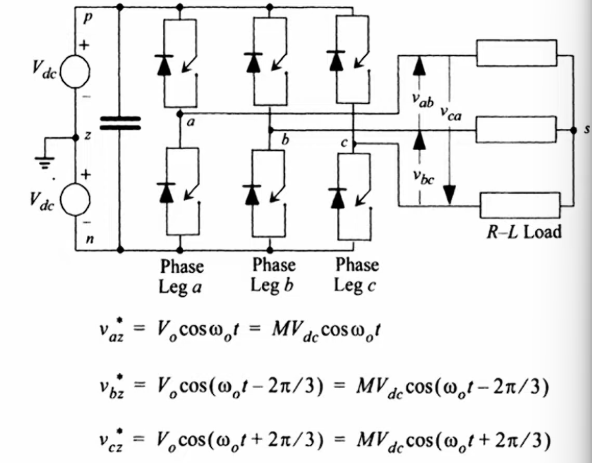

## Polynomial Division Method: diophantine


$$\frac{C\left(z^{-1} \right)}{A\left(z^{-1} \right)}=\textrm{Ej}\left(z^{-1} \right)+\left(z^{-j} \right)\;\ldotp \;\left\lbrack \frac{\textrm{Fj}\left(z^{-1} \right)}{A\left(z^{-1} \right)}\right\rbrack$$


Where A($z^{-1}$) = ΔA($z^{-1}$) = (1 - $z^{-1}$) . A

%% Função para o cálculo da equação diofantina

function [E,F] = diofantina(A,N1,N2)

    % Cálculo dos polinômios E(z) e F(z)
    
    nA = size(A,2); % ordem de A(z)
    
    % Cálculo de F(z)
    f(1,:) = [1 zeros(1,nA-2)]; % inicializa F
    
    for j=1:N2
        for i=1:nA-2
            f(j+1,i) = f(j,i+1)-f(j,1)*A(i+1);
        end
        f(j+1,nA-1) = -f(j,1)*A(nA);
    end
    
    F = f(1+N1:1+N2,:);
    
    % Cálculo de E(z)
    E = zeros(N2);
    e(1) = 1;
    E(1,1) = e(1);
    
    for i=2:N2
        e(i) = f(i,1);
        E(i,1:i) = e;
    end
    
    E = E(N1:N2,:);


end

%% Função para o cálculo da equação diofantina

function [E,F] = diofantinaC(A,C,N1,N2)

% Cálculo dos polinômios E(z) e F(z)
% delta = [1 -1]; % delta = 1-z^{-1}
% AD = conv(A,delta) ; % AD = A(z)*Delta(z)

nA1 = size(A,2); % numero de elemnetos de A(z)
nC = size(C,2); % numero de elementos de C(z)


%%% calculo da ordem máxima do polinômio F
nF1 = max(nC,N1-1+nA1)-N1;
nF2 = max(nC,N2-1+nA1)-N2;
nF = max(nF1,nF2);

% Cálculo de F(z)

if(nC>nA1)
    A = [A zeros(1,nC-nA1)];
    nA = size(A,2);

else
    nA = nA1;
end

f(1,:) = [C zeros(1,nA-nC)]; % inicializa F



for j=1:N2
    for i=1:nA-1
        f(j+1,i) = f(j,i+1)-f(j,1)*A(i+1);
    end
%     f(j+1,nA-1) = -f(j,1)*A(nA);
end

F = f(1+N1:1+N2,1:nF);



% Cálculo de E(z)
E = zeros(N2);
e(1) = C(1);
E(1,1) = e(1);

for i=2:N2
    e(i) = f(i,1);
    E(i,1:i) = e;
end

E = E(N1:N2,:);


 
end

